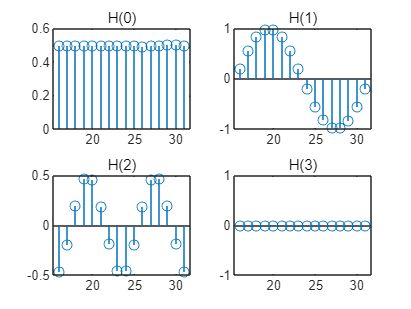

clc;clear;
f = 50;  % 基波频率
A = [0.5, 1, 0.5, 2];  % 振幅
phi = [0, pi/2, pi, -pi/2];  % 相位
N = 16;  % 采样频率倍数
L = 2 * N;  % 采样点数
fs = N * f;  % 采样频率
T = 1 / fs;  % 采样间隔
t = (0:L-1) * T;  % 采样时间
tt=N:L-1;%序列号
s = zeros(size(t));  % 初始化采样信号
for k = 1:length(A)
    sk = A(k) * cos(2 * pi * (k-1) * f * t + phi(k));
    s = s + sk;
end
r=0.999;
y=CombFilter(s,N,r);%梳状
H = zeros(1, N); % 初始化频域响应
H(1) = 1; 
H(2) = exp(-1i*pi*(N-1)/N);
H(3) = exp(-1i*2*pi*(N-1)/N);
H(15) = -exp(-1i*14*pi*(N-1)/N); 
H(16) = -exp(-1i*15*pi*(N-1)/N);
% 提取各频点的响应并进行谐振器处理
y0=Resonator2(y,N,r,0,H(1));%提取响应
y0=y0/N;%归一
y0=y0(N+1:2*N);%提取数据
y1=Resonator2(y,N,r,1,H(2));
y1=y1/N;
y1=y1(N+1:2*N);
y2=Resonator2(y,N,r,2,H(3));
y2=y2/N;
y2=y2(N+1:2*N);
y3=Resonator2(y,N,r,3,H(4));
y3=y3/N;
y3=y3(N+1:2*N);
subplot(2,2,1);
stem(tt,y0);
title('H(0)');
subplot(2,2,2);
stem(tt,y1);
title('H(1)');
subplot(2,2,3);
stem(tt,y2);
title('H(2)');
subplot(2,2,4);
stem(tt,y3);
title('H(3)');